clc; clear;close all;clf;
load direction_sf_tf_data.mat
clear orientation_direction_bayes

cell_num = 72

cell_num = 72

curve_num = 5

curve_num = 5

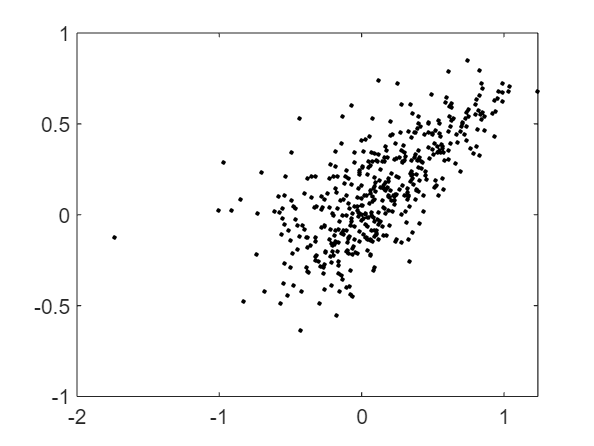

I = struct('Rp',logspace(log10(.5),log10(150),100), ...
    'Op',0:5:359, ...
    'Alpha',linspace(0,1,50), ...
    'Sig',logspace(log10(5),log10(90),20));
m = [];
v = [];
for cell_num = cell_num
    v = [v,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_stderr];
    m = [m,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_mean];
end
figure(),plot(log10(m),log10(v),'k.'),

mdl = fitlm(log10(m),log10(v)),

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)    0.076965     0.01006    7.6507     1.244e-13
    x1              0.48696    0.023814    20.448    4.7596e-66

Number of observations: 448, Error degrees of freedom: 446
Root Mean Squared Error: 0.204
R-squared: 0.484,  Adjusted R-Squared: 0.483
F-statistic vs. constant model: 418, p-value = 4.76e-66

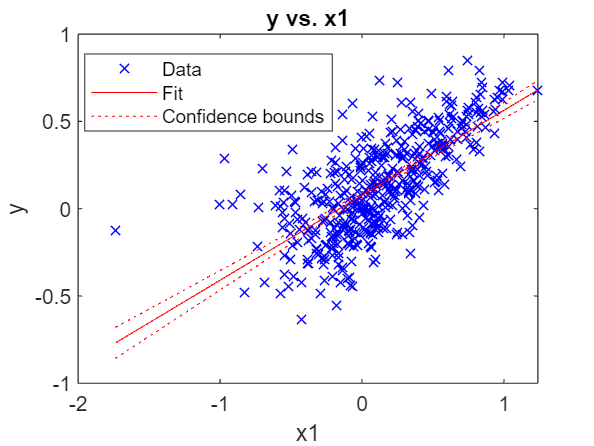

figure(),plot(mdl);

noise_coefficients = mdl.Coefficients{:,1};

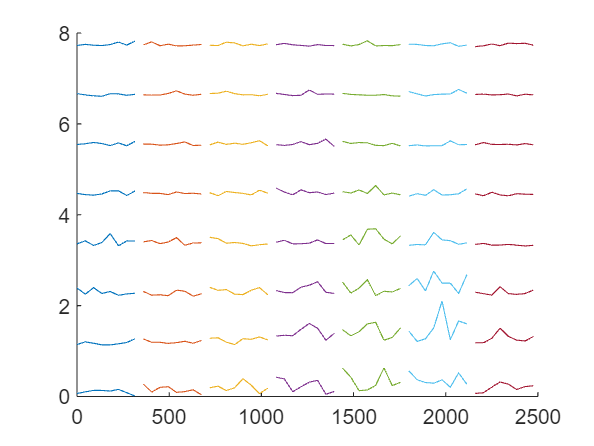

data = extract_direction_data(direction_data_s{cell_num});
figure(),plot_dir_sf_tf(direction_data_s{cell_num});

tic;
[output,Lik] = bayes_grid_function_proportional_noise(I,data(curve_num),noise_coefficients);

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

toc;

Elapsed time is 70.064405 seconds.


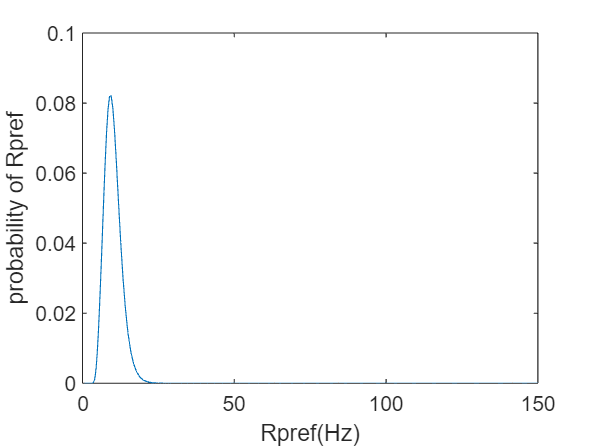

ans = 1

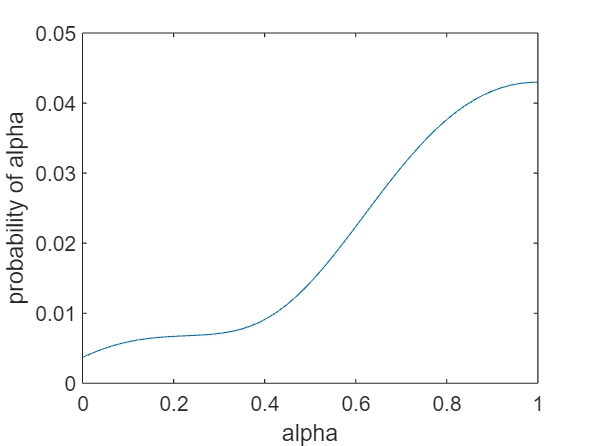

ans = 2

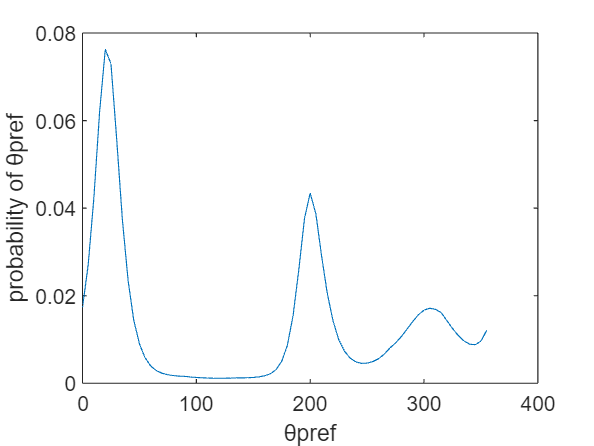

ans = 3

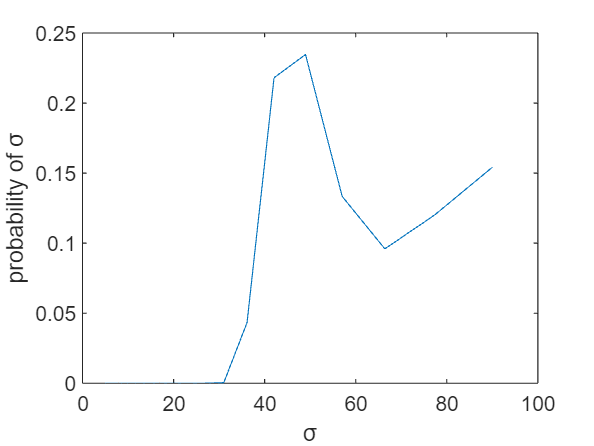

ans = 4

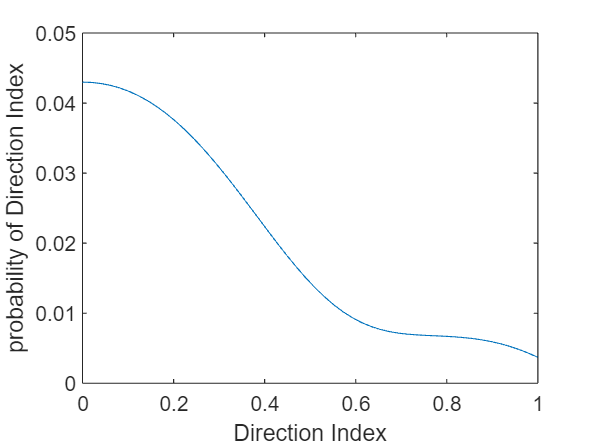

plot_bayes_oridir(output)

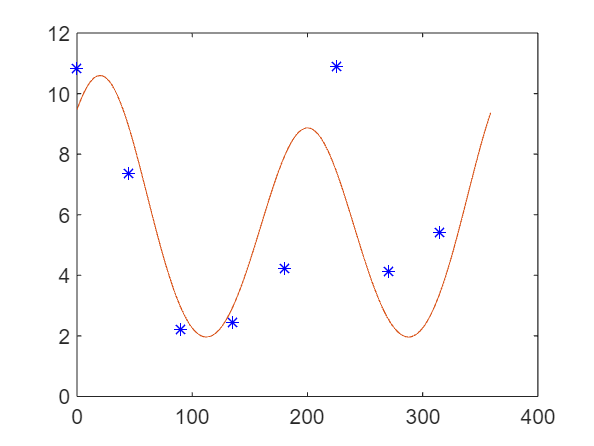

figure(),plot(data(curve_num).angle,data(curve_num).mean_responses,'b*',0:359,output.marginal_likelihood.Rsp.likelihoods)